# **24774 - Lab 1: Controller Design and Implementation**

# **Group 4: Emma Benjaminson, Pranav Narahari, and Keitaro Nishimura**

% Nominal Plant Model 
quanser_aero_parameters;
quanser_aero_state_space;

% References 
% note: only use square waves for references
yaw_ref = pi/4; % radians
yaw_freq = 0.5; % rad/s
pitch_ref = pi/6; % radians
pitch_freq = 0.4; % rad/s

## Preliminaries

- Plot the plant's Bode plot. Comment on any unusual features that you see.

- Build the Simulink model based on the nominal plant and include a saturation nonlinearity that limits control voltages to $\pm$25 V. You will use this simulation to test your controllers' performance before you test them on the hardware.

### 1. Bode Plot

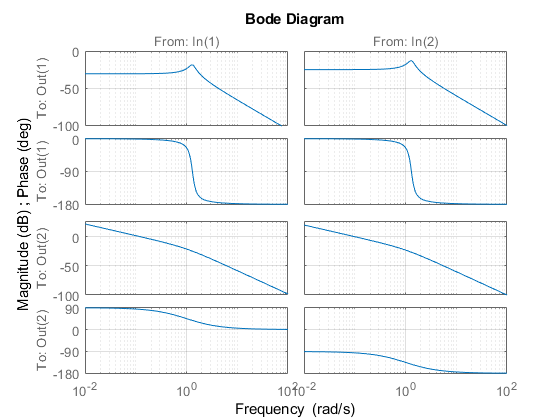

G_nom = ss(A,B,C,D);
bode(G_nom)
grid minor

We can see from the bode plot that the system is heavily coupled. In stead of a clean identity matrix both the 1,1 and 1,2 not doing much as their magnituds are below 0db and the 2,1 and 2,2 tfs doing most of the work. This is backed up by our previous experience with the hardware where the pitch would be pushing the whole system with the yaw motor just trying it's best but not getting anything done. Like me lol

### 2. Simulink model

Check the aero_simulation simulink file for the model.

## Classical Control

- Design a diagonal PID feedback controller, i.e., design and implement two SISO PID controllers, one for each of the diagonal Plant entries. Adjust your design around the simulation model to anticipate the effects of saturation. 

- Design a DIDO feedback controller based on your model and diagonal controller using dynamic decoupling. In dynamic decoupling, controllers are designed for a shaped plant $G_s =G_D G_M^{-1} G$ where $G_M$ is the plant model, $G_D$ is the diagonal inverse. Assuming that your decoupling controller works properly, your diagonal controller should be effective for the shaped plant. As before, test the performance in hardware using the reference discussed above. NOTE: Your final controller should be $K=G_M^{-1} G_D K_D$ where $K_D$ is the diagonal controller you designed previously.

### 1. PID Control

First let's take a look at the root locus of the diagonal tfs

% First let's take a look at the 1,1 tf
ss1 = G_nom(1,1);
[b, a] = ss2tf(ss1.A, ss1.B, ss1.C, ss1.D);
tf1 = tf(b,a)


tf1 =
 
   0.05026 s^2 + 0.05028 s + 1.116e-17
  -------------------------------------
  s^4 + 1.325 s^3 + 2.037 s^2 + 1.712 s
 
Continuous-time transfer function.



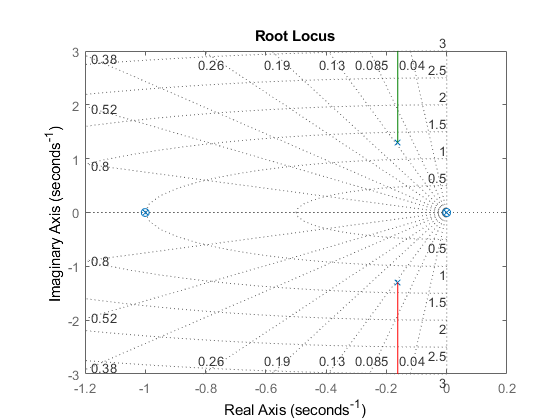

rlocus(tf1)
grid minor

Now let's see how the root locus changes by adding PID

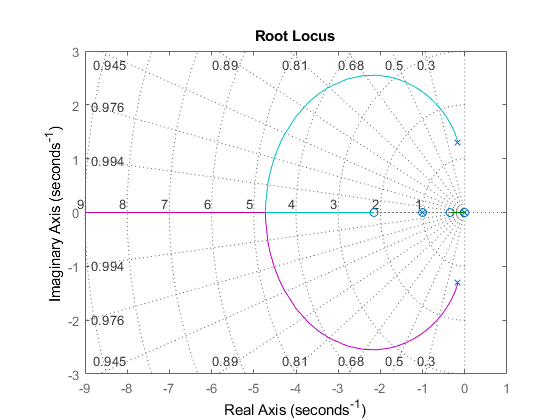

Kp_1 = 200;
Ki_1 = 60;
Kd_1 = 80;
C1 = pid(Kp_1, Ki_1, Kd_1);
C1_tf = tf(C1);
rlocus(C1_tf*tf1)
grid minor

% Now let's do the 2,2 tf
ss2 = G_nom(2,2);
[b, a] = ss2tf(ss2.A, ss2.B, ss2.C, ss2.D);
tf2 = tf(b, a)


tf2 =
 
       0.1 s^2 + 0.0325 s + 0.1712
  -------------------------------------
  s^4 + 1.325 s^3 + 2.037 s^2 + 1.712 s
 
Continuous-time transfer function.



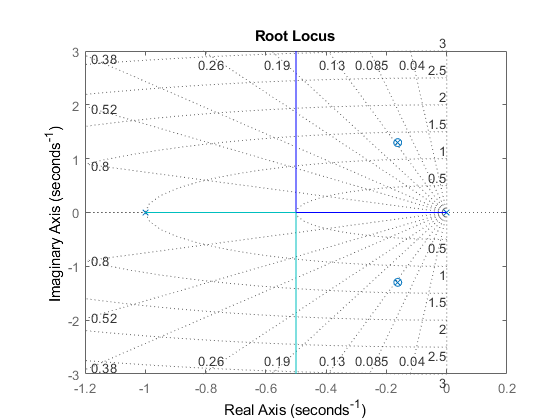

rlocus(tf2)
grid minor

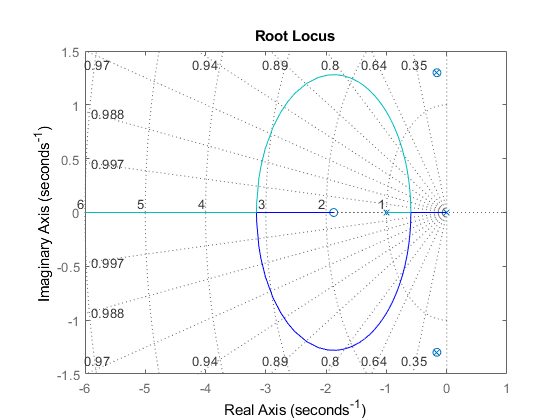

Kp_2 = 150;
Ki_2 = 0;
Kd_2 = 80;
C2 = pid(Kp_2, Ki_2, Kd_2);
C2_tf = tf(C2);
rlocus(C2_tf*tf2);
grid minor

### 2. Dynamic Decoupling

s = tf('s');
G_diag = [ss1  0;
          0    ss2];
% From earlier we know that the tf for model are not proper so we need to
% add more poles to the inverse to make it so. 
K = 1e2; % Adding plose at high freq to make tf proper
G_inv = inv(G_nom)*(1/((s/K)+1))^2;
bodemag(inv(G_nom), G_inv)
Kd = [C1 0;0 C2];
halp = G_inv * G_diag * Kd;
halp = minreal(halp);

17 states removed.


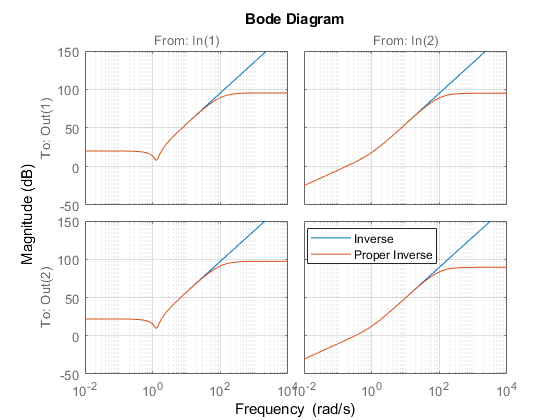

halp_z = c2d(halp, 0.002, 'zoh');
halp_z_ss = canon(halp_z, 'modal');
grid minor
legend('Inverse', 'Proper Inverse', 'location', 'best')

Looks good and seems like we were able to make it proper.

## State Space Control

- Quanser's approach to state estimation is differentiation of position measurements followed by a low-pass filter (LPF). Design an observer (Luenberger observer or Kalman filter (KF)) to estimate the rotation rates.

- Now that we have an estimate of the full state (you can use the Quanser estimates for this), we can design a state feedback controller that tracks the reference. Design a state feedback controller (pole placement or LQR) to track the refrence signals. 

### 1. Observer